clear all

allResults = sensiAna_YJM(0.1,1);

allResults.maxT

ans = struct with fields:
      prop_R0: [2.9732 2.7926 2.7490]
    homophily: [2.6720 2.7926 3.1344]
     alpha_P0: [2.7792 2.7926 2.8045]
     alpha_P1: [2.4032 2.7926 2.9036]
     alpha_R0: [2.7820 2.7926 2.8034]
      omega_R: [2.7852 2.7926 2.7995]
      omega_P: [2.8003 2.7926 2.7859]
        Omega: [2.7966 2.7926 2.7884]
         Td_c: [2.8435 2.7926 2.7057]
          k_P: [2.7866 2.7926 2.7979]
          k_R: [2.7979 2.7926 2.7874]
          c_R: [2.8201 2.7926 2.7633]
          c_P: [2.7460 2.7926 2.8074]
        kappa: [3.2618 2.7926 2.2623]
        delta: [2.8625 2.7926 2.7125]
           s_: [2.8195 2.7926 2.7727]
        C_at0: [2.7939 2.7926 2.7913]
        C_oc0: [2.7955 2.7926 2.7901]
       C_veg0: [2.7950 2.7926 2.7919]
        C_so0: [2.7922 2.7926 2.7937]
          k_p: [2.8057 2.7926 2.7992]
          k_c: [2.7938 2.7926 2.7914]
          k_M: [2.8037 2.7926 2.7862]
          k_r: [2.7934 2.7926 2.8119]
          E_a: [2.8071 2.7926 2.7929]
         k_sr: [2.7942 2

res_ = allResults;
resNames = fieldnames(allResults.maxT);

give2barh = [];
fldnames  = fieldnames(res_.maxT);
for i =1:length(fldnames  )
    fldname_ = fldnames{i};
    give2barh = [give2barh; res_.maxT.(fldname_)];
end

ctst = categorical(fldnames)'

ctst = 1×39 categorical array
     prop_R0      homophily      alpha_P0      alpha_P1      alpha_R0      omega_R      omega_P      Omega      Td_c      k_P      k_R      c_R      c_P      kappa      delta      s_      C_at0      C_oc0      C_veg0      C_so0      k_p      k_c      k_M      k_r      E_a      k_sr      k_t      c      A      S      tao_CH4      P_0      F_0      chi      zeta      f_max      omega      T_c      t_f 


% sort A in descending order (decreasing A values) 
% and keep the sort index in "sortIdx"
%[A,sortIdx] = sort(std(give2barh'),'descend');
%sizeBar = abs((give2barh(:,1))' - (give2barh(:,2))') + abs((give2barh(:,2))' - (give2barh(:,3))');
max_temp = max(give2barh, [],2);
min_temp = min(give2barh, [],2);
sizeBar = abs((max_temp)' - (give2barh(:,2))' + (give2barh(:,2))' - (min_temp)');
[A,sortIdx] = sort(sizeBar,'ascend');

% sort B using the sorting index
B = give2barh(sortIdx,:);
sortedNames = categorical(resNames(sortIdx))';
%sortedNames = reordercats(sortedNamesNice, fliplr(namesNice));
mn1 = mean(give2barh);
mn1 = mn1(2); 

resNames

resNames = 39×1 cell array
    {'prop_R0'  }
    {'homophily'}
    {'alpha_P0' }
    {'alpha_P1' }
    {'alpha_R0' }
    {'omega_R'  }
    {'omega_P'  }
    {'Omega'    }
    {'Td_c'     }
    {'k_P'      }
    {'k_R'      }
    {'c_R'      }
    {'c_P'      }
    {'kappa'    }
    {'delta'    }
    {'s_'       }
    {'C_at0'    }
    {'C_oc0'    }
    {'C_veg0'   }
    {'C_so0'    }
    {'k_p'      }
    {'k_c'      }
    {'k_M'      }
    {'k_r'      }
    {'E_a'      }
    {'k_sr'     }
    {'k_t'      }
    {'c'        }
    {'A'        }
    {'S'        }


resNames(8)

ans = 1×1 cell array
    {'Omega'}


disp(apple)

Unrecognized function or variable 'apple'.

temp_str = resNames(1); % cell
if strcmp(temp_str{1}, 'homophily')
    resNames(2) = {'\alpha_{P0}'};
    resNames(3) = {'\alpha_{P1}'};
    resNames(4) = {'\alpha_{R0}'};
    resNames(5) = {'I_{R0}'};
    resNames(6) = {'I_{P0}'};
    resNames(8) = {'\Omega'};
    temp_str2 = resNames(11);
    if strcmp(temp_str2{1}, 'kappa')
        incr = 1;
        resNames(11) ={'\kappa'};
    else
        incr = 0;
    end
    
    resNames(11+incr) = {'\delta'};
    resNames(15+incr) = {'C_{at0}'};
    resNames(16+incr) = {'C_{oc0}'};
    resNames(17+incr) = {'C_{veg0}'};
    resNames(18+incr) = {'C_{so0}'};
    resNames(24+incr) = {'k_{sr}'};
    resNames(29+incr) = {'\tau_{CH4}'};
    resNames(33+incr) = {'\chi'};
    resNames(34+incr) = {'\zeta'};
    resNames(35+incr) = {'f_{max}'};
    resNames(36+incr) = {'\omega'};
end
if strcmp(temp_str{1}, 'prop_R0')
    resNames(1) = {'\rho_R'};
    resNames(3) = {'\alpha_{P0}'};
    resNames(4) = {'\alpha_{P1}'};
    resNames(5) = {'\alpha_{R0}'};
    resNames(6) = {'\omega_R'};
    resNames(7) = {'\omega_P'};
    resNames(8)={'\Omega'};
    temp_str2 = resNames(14);
    if strcmp(temp_str2{1}, 'kappa')
        incr = 3;
        resNames(14) ={'\kappa'};
    else
        incr = 0;
    end    
    
    resNames(12+incr) = {'\delta'};
    resNames(14+incr) = {'C_{at0}'};
    resNames(15+incr) = {'C_{oc0}'};
    resNames(16+incr) = {'C_{veg0}'};
    resNames(17+incr) = {'C_{so0}'};
    resNames(23+incr) = {'k_{sr}'};
    resNames(28+incr) = {'\tau_{CH4}'};
    resNames(31+incr) = {'\chi'};
    resNames(32+incr) = {'\zeta'};
    resNames(33+incr) = {'f_{max}'};
    resNames(34+incr) = {'\omega'};
end


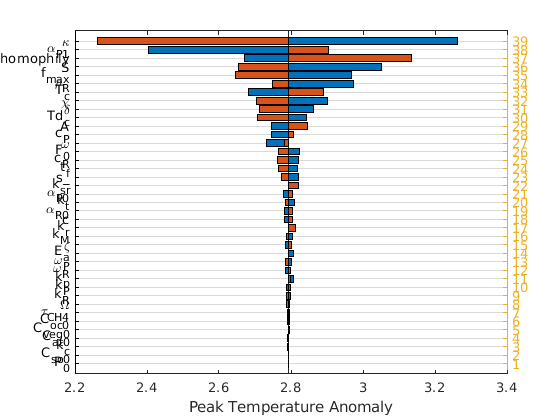

clf
barh(give2barh(sortIdx,1), 'stacked', 'BaseValue', mn1)
hold on
barh(give2barh(sortIdx,3),'stacked', 'BaseValue', mn1)
len__ = length(sortIdx);
yticks(1:len__)
set(gca, "YTickLabel", resNames(sortIdx))
title('')
xlabel("Peak Temperature Anomaly")
ax=gca;ax.YGrid='on';
yyaxis right
yticks(1:1:39)

disp(apple)

Unrecognized function or variable 'apple'.

% Instead of varying prop_R0 and fixing x0=0.05, vary x0 and fix prop_R0 = 0.25

clear all
allResults = sensiAna_YJM(0.1,0);

allResults.maxT
res_ = allResults;
resNames = fieldnames(allResults.maxT);

give2barh = [];
fldnames  = fieldnames(res_.maxT);
for i =1:length(fldnames  )
    fldname_ = fldnames{i};
    give2barh = [give2barh; res_.maxT.(fldname_)];
end

ctst = categorical(fldnames)'
% sort A in descending order (decreasing A values) 
% and keep the sort index in "sortIdx"
%[A,sortIdx] = sort(std(give2barh'),'descend');
%sizeBar = abs((give2barh(:,1))' - (give2barh(:,2))') + abs((give2barh(:,2))' - (give2barh(:,3))');
max_temp = max(give2barh, [],2);
min_temp = min(give2barh, [],2);
sizeBar = abs((max_temp)' - (give2barh(:,2))' + (give2barh(:,2))' - (min_temp)');
[A,sortIdx] = sort(sizeBar,'ascend');

% sort B using the sorting index
B = give2barh(sortIdx,:);
sortedNames = categorical(resNames(sortIdx))';
%sortedNames = reordercats(sortedNamesNice, fliplr(namesNice));
mn1 = mean(give2barh);
mn1 = mn1(2); 

resNames

resNames(33)

temp_str = resNames(1); % cell
if strcmp(temp_str{1}, 'homophily')
    resNames(2) = {'\alpha_{P0}'};
    resNames(3) = {'\alpha_{P1}'};
    resNames(4) = {'\alpha_{R0}'};
    resNames(5) = {'\omega_R'};
    resNames(6) = {'\omega_P'};
    
    temp_str2 = resNames(11);
    if strcmp(temp_str2{1}, 'kappa')
        incr = 0;
        resNames(11) ={'\kappa'};
    else
        incr = 0;
    end
    
    resNames(11+incr) = {'\delta'};
    resNames(15+incr) = {'C_{at0}'};
    resNames(16+incr) = {'C_{oc0}'};
    resNames(17+incr) = {'C_{veg0}'};
    resNames(18+incr) = {'C_{so0}'};
    resNames(24+incr) = {'k_{sr}'};
    resNames(29+incr) = {'\tau_{CH4}'};
    resNames(32+incr) = {'\chi'};
    resNames(33+incr) = {'\zeta'};
    resNames(34+incr) = {'f_{max}'};
    resNames(35+incr) = {'\omega'};
end
if strcmp(temp_str{1}, 'prop_R0')
    resNames(1) = {'prop_{R0}'};
    resNames(3) = {'\alpha_{P0}'};
    resNames(4) = {'\alpha_{P1}'};
    resNames(5) = {'\alpha_{R0}'};
    resNames(6) = {'\omega_R'};
    resNames(7) = {'\omega_P'};
    
    temp_str2 = resNames(12);
    if strcmp(temp_str2{1}, 'kappa')
        incr = 1;
        resNames(12) ={'\kappa'};
    else
        incr = 0;
    end    
    
    resNames(12+incr) = {'\delta'};
    resNames(14+incr) = {'C_{at0}'};
    resNames(15+incr) = {'C_{oc0}'};
    resNames(16+incr) = {'C_{veg0}'};
    resNames(17+incr) = {'C_{so0}'};
    resNames(23+incr) = {'k_{sr}'};
    resNames(28+incr) = {'\tau_{CH4}'};
    resNames(31+incr) = {'\chi'};
    resNames(32+incr) = {'\zeta'};
    resNames(33+incr) = {'f_{max}'};
    resNames(34+incr) = {'\omega'};
end

barh(ctst, give2barh, 'BaseValue', mn1)

clf
barh(give2barh(sortIdx,:), 'BaseValue', mn1)
len__ = length(sortIdx);
yticks(1:len__)
set(gca, "YTickLabel", resNames(sortIdx))
title('Sensitivities; 0.1 from baseline; \nu\neq1')

if ~(1==0)
    disp('hello')
end
